# rs-fMRI time series data

% The script load the subset of processed rs-fMRI data used in study
%Huang, S.-G., Samdin, S.B., Ting, C.M., Ombao, H., Chung, M.K. 
%2020 Statistical model for dynamically-changing correlation matrices 
%with application to brain connectivity. Journal of Neuroscience 
%Methods 331:108480
%
% The data went through the minimal preprocssing related to head motions:
% FD based motion correction, scrubing and imputation. 
% Also the data is centered to the mean since every 
% subject has different amount of brain activation. 
% Other image processing such as bandpass filtering and basis expansion 
% are not applied. 
%
%http://pages.stat.wisc.edu/~mchung/papers/huang.2020.NM.pdf
%
%Do not distribute the data or upload to other sites. 
%This is not public domain or copyright free data. 
%% If you are using the data for publication, please reference the paper above.
%
%
% (C) 2021- Moo K. Chung  mkchung@wisc.edu
%     University of Wisconsin-Madison
%     
% Created 2021 Jun 07
% Edited  2021 Dec 20, 2022 Oct 2, 2023 August9
%
%
%% The neuroscienfific question worth persuing is if rs-fMRI data is 
%% showing different patterns between different regions of brains. 
%% The following regions of the brain are carefully picked. 
%
%
% 15 F3OG Left orbital part of interior frontal gyrus
% 16 F3OD Right orbital part of intferior frontal gyrus
% 37 HIPPOG Left hipocampus
% 38 HIPPOD Right hippocampus
% 51 O2G Left middle occipital 
% 52 O2D Right middle occipital

%Variable rsfMRI is of size 1200 x 6 x 100.
%There are 1200 time points, 6 brain regions (indexed exactly as above)
%for 100 subjects. 

load rsfMRI.mat


## Is brain topologically symmetric across hemispheres?

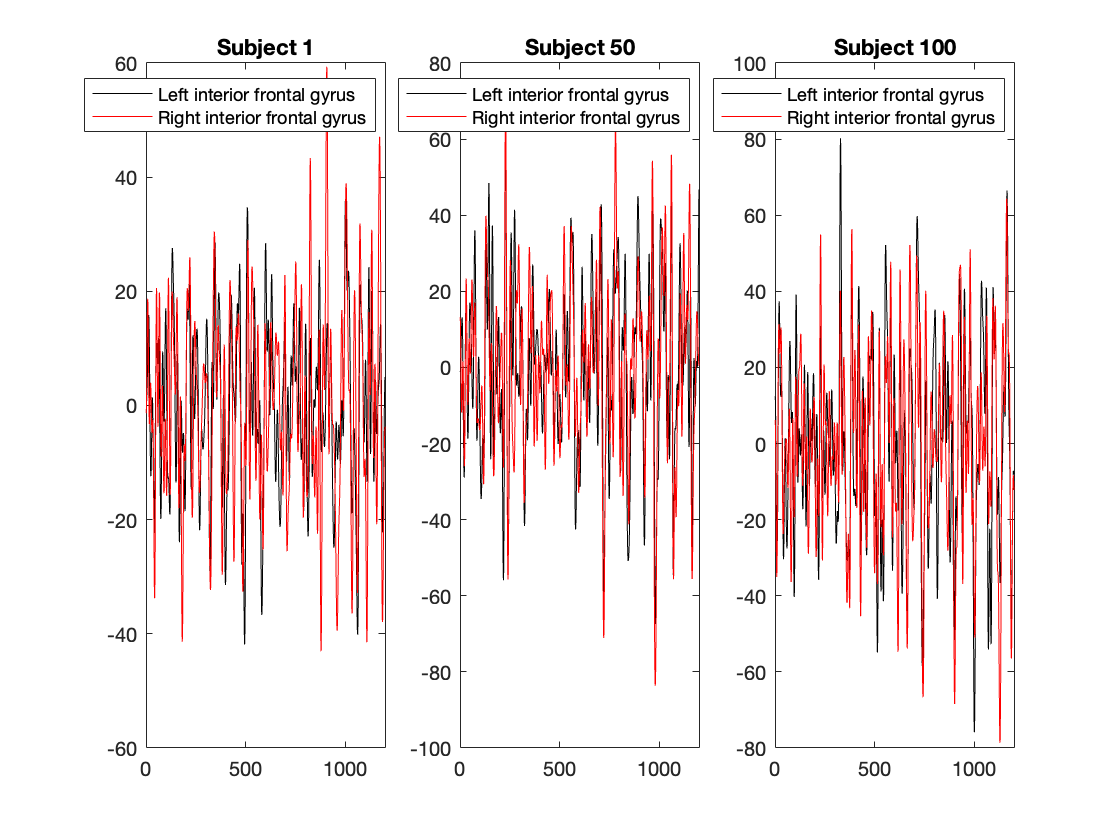

%Display rs-fMRI of the first subject. 
figure; subplot(1,3,1); plot(rsfMRI(:,1,1), 'k'); 
hold on; plot(rsfMRI(:,2,1), 'r');
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')
title('Subject 1')
%We can see a fair bit of symmetric and syncronization pattern.

subplot(1,3,2);; plot(rsfMRI(:,1,50), 'k'); 
hold on; plot(rsfMRI(:,2,50), 'r')
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')
title('Subject 50')

subplot(1,3,3);; plot(rsfMRI(:,1,100), 'k'); 
hold on; plot(rsfMRI(:,2,100), 'r')
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')
title('Subject 100')

%The first few time points (about 10 to 60 time points) are considered as 
%outliers and can be removed. The start of scanning that cause various noise. 
%However, the last time points are not outliers. 

% Q1: Are rs-fMRI topoligically identical between left and right hemispheres?
% Q2: How to perform statistical analysis on 100 subjects?

## Are brain activities topologically different across different brain regions?

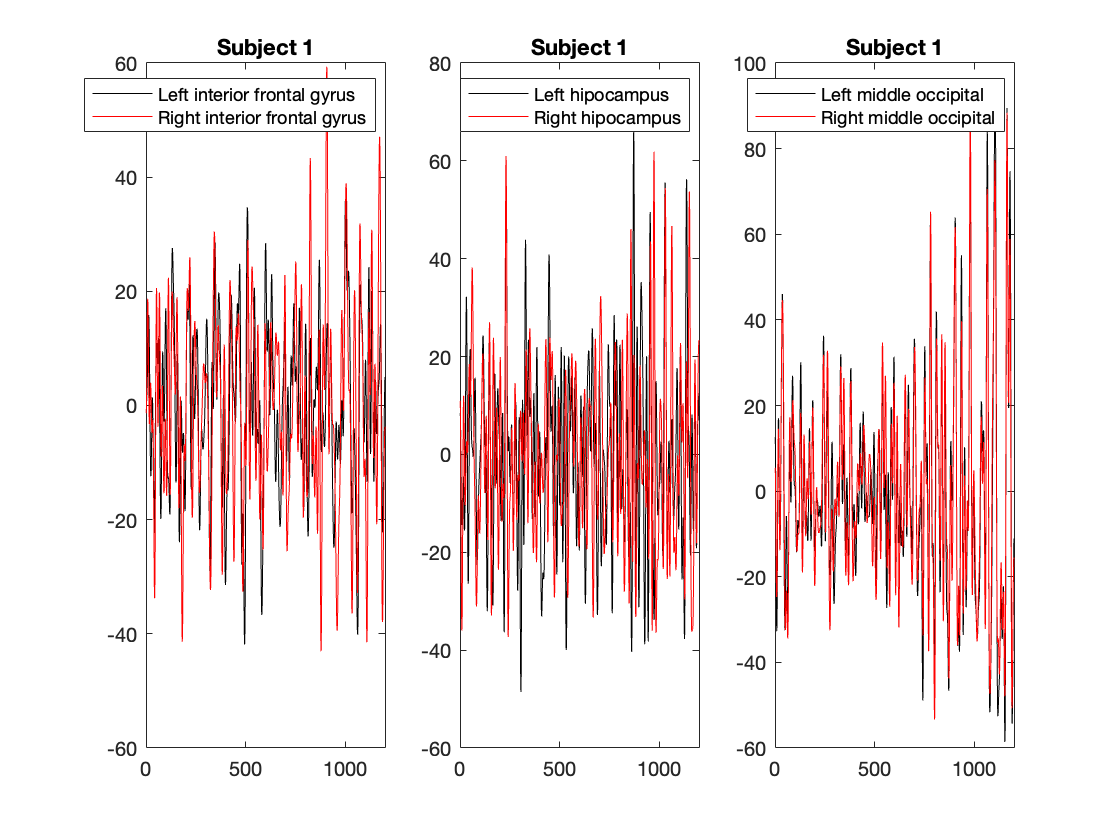

%Display rs-fMRI of the first subject. 
figure; subplot(1,3,1); plot(rsfMRI(:,1,1), 'k'); 
hold on; plot(rsfMRI(:,2,1), 'r');
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')
title('Subject 1')
%We can see a fair bit of symmetric and syncronization pattern.

subplot(1,3,2);; plot(rsfMRI(:,3,50), 'k'); 
hold on; plot(rsfMRI(:,4,50), 'r')
legend('Left hipocampus', 'Right hipocampus')
title('Subject 1')

% 37 HIPPOG Left hipocampus
% 38 HIPPOD Right hippocampus
% 51 O2G Left middle occipital 
% 52 O2D Right middle occipital

subplot(1,3,3);; plot(rsfMRI(:,5,100), 'k'); 
hold on; plot(rsfMRI(:,6,100), 'r')
legend('Left middle occipital', 'Right middle occipital')
title('Subject 1')

## Do NOT average across subjects 

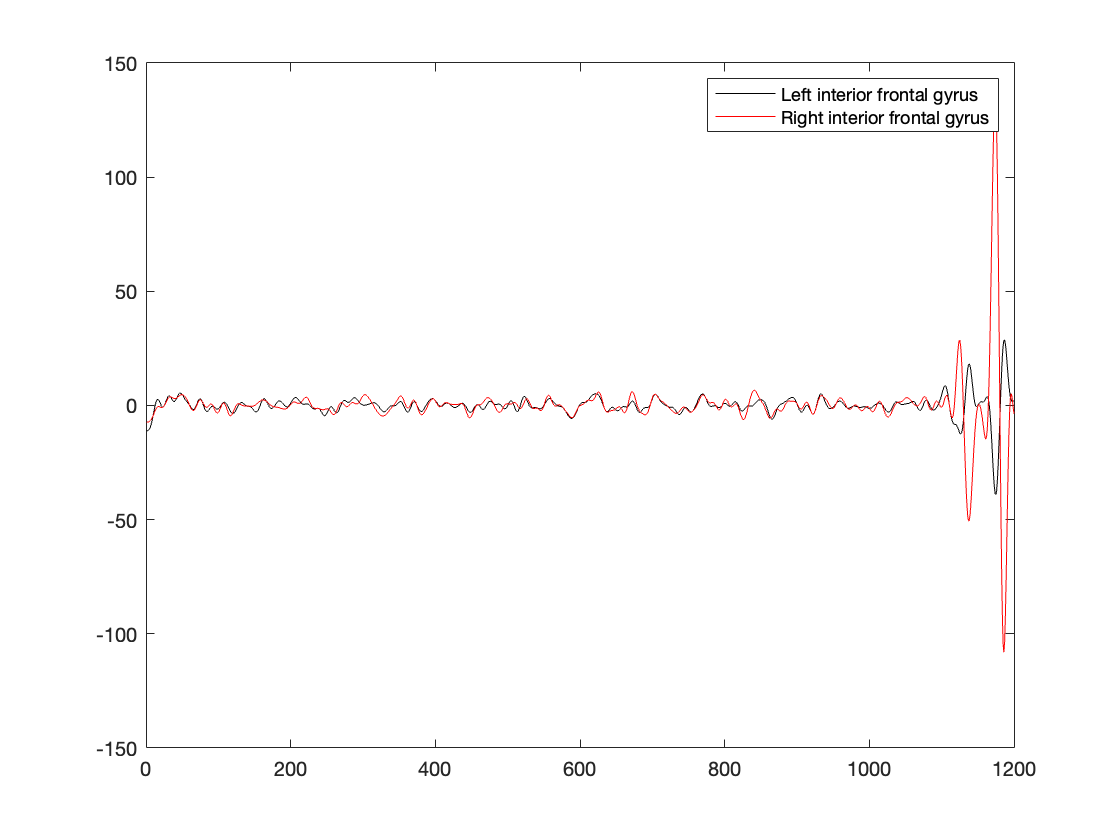

% Do not avarge all 100 subjects and display. This is total nonsense.
% Timewise, brain activities do not synchronize across subjects.
%
% Suggestion: What should have been done is doing Fourier expansion. 
% Then average within specific frequency or bandpass.
% That will match across subjects.  

avgfMRI = mean(rsfMRI,3); %avearging over 100 subjects
figure; plot(avgfMRI(:,1), 'k')
hold on; plot(avgfMRI(:,2), 'r')
legend('Left interior frontal gyrus', 'Right interior frontal gyrus')

% The averge pattern is mostly white noise. The last time points
% (1100-1200) are likely to be caused by the termination of experiment.  

% Additional scientific questions
%
% 1) Is the brain activity topologically changing over time?
% 2) is the topological pattern repeating (periodic) or random?
% 3) Are rs-fMRI pattern different in 3 different regions of the brain.














